%B11102112 李家睿

load wecg.mat

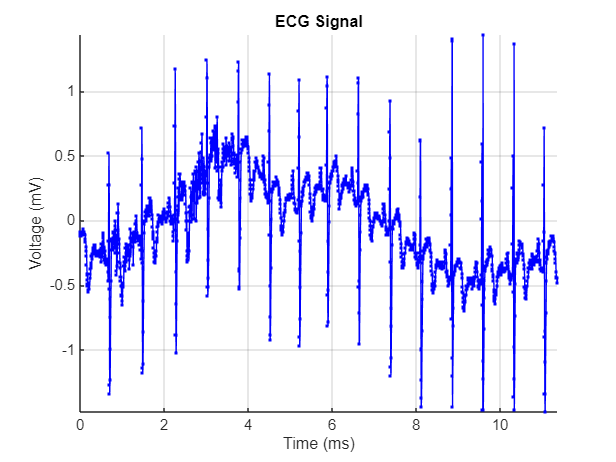

fs = 180; % Define the sampling frequency
t_ms = (0:length(wecg)-1)/fs; % Time vector
 
% Create a new figure window for plotting.
figure;
handle.fig1 = gcf; % Get the current figure
handle.axes1 = axes('parent', handle.fig1); % Set up axes in the figure

% Create the ECG plot line
handle.line1 = line('parent', handle.axes1);

% Set plot labels, title, and grid
xlabel('Time (ms)');
ylabel('Voltage (mV)');
title('ECG Signal');
grid on;
xlim([min(t_ms) max(t_ms)]); % Set x-axis limits based on the time vector
ylim([min(wecg) max(wecg)]); % Set y-axis limits based on the ECG signal

% Animate the plot
for i = 1:length(wecg)
    % Update the line data for the ECG signal
    set(handle.line1, 'XData', t_ms(1:i), 'YData', wecg(1:i), 'Color', 'b', 'Marker', '.');
    
    % Pause to control the speed of the animation
    pause(0.0001); % Adjust the pause value to control animation speed
    drawnow; % Update the figure window
end

%Today's lab is quite interesting and fun